% List of benign image names
benignImages = {'ISIC_0000001.jpg', 'ISIC_0000017.jpg', 'ISIC_0000028.jpg', 'ISIC_0000062.jpg', 'ISIC_0000065.jpg', 'ISIC_0000130.jpg', 'ISIC_0000240.jpg', 'ISIC_0000261.jpg', 'ISIC_0000265.jpg', 'ISIC_0000381.jpg', 'ISIC_0000383.jpg', 'ISIC_0000384.jpg', 'ISIC_0000386.jpg', 'ISIC_0000396.jpg', 'ISIC_0000397.jpg', 'ISIC_0000409.jpg', 'ISIC_0000416.jpg', 'ISIC_0000427.jpg', 'ISIC_0000431.jpg', 'ISIC_0000455.jpg', 'ISIC_0000460.jpg', 'ISIC_0000483.jpg', 'ISIC_0000488.jpg', 'ISIC_0000489.jpg', 'ISIC_0000495.jpg', 'ISIC_0000507.jpg', 'ISIC_0009871.jpg', 'ISIC_0009883.jpg', 'ISIC_0009884.jpg', 'ISIC_0009914.jpg'};  

% List of malignant image names
malignantImages = {'ISIC_0000029.jpg', 'ISIC_0000054.jpg', 'ISIC_0000152.jpg', 'ISIC_0000390.jpg', 'ISIC_0001106.jpg', 'ISIC_0009868.jpg', 'ISIC_0009905.jpg', 'ISIC_0009950.jpg', 'ISIC_0009960.jpg', 'ISIC_0009971.jpg', 'ISIC_0010036.jpg', 'ISIC_0010080.jpg', 'ISIC_0010225.jpg', 'ISIC_0010241.jpg', 'ISIC_0010251.jpg', 'ISIC_0010265.jpg', 'ISIC_0010321.jpg', 'ISIC_0010350.jpg', 'ISIC_0010358.jpg', 'ISIC_0010364.jpg', 'ISIC_0010372.jpg', 'ISIC_0010380.jpg', 'ISIC_0010466.jpg', 'ISIC_0010468.jpg', 'ISIC_0010476.jpg', 'ISIC_0010576.jpg', 'ISIC_0010852.jpg', 'ISIC_0010860.jpg', 'ISIC_0011118.jpg', 'ISIC_0011135.jpg', 'ISIC_0011137.jpg', 'ISIC_0011140.jpg', 'ISIC_0011163.jpg', 'ISIC_0011169.jpg', 'ISIC_0011366.jpg'};  

results = cell(size(featuresMatrix, 1), 3);

% Combine the image names into one list
imageNames = [benignImages, malignantImages];  

% Create a corresponding label list
labels = [repmat({'Benign'}, 1, length(benignImages)), repmat({'Malignant'}, 1, length(malignantImages))];

% Assuming benignFeatures and malignantFeatures are your feature matrices

% Compute the mean feature vector for each class
meanBenign = mean(benignFeatures, 1);  % Mean feature vector for benign
meanMalignant = mean(malignantFeatures, 1);  % Mean feature vector for malignant

% Combine the two mean vectors to form the initial centroids
initialCentroids = [meanBenign; meanMalignant];  % 2xN matrix (2 clusters)

% Number of replicates
numReplicates = 10;

% Extract features for clustering (ensure 'reducedFeatureTable' is defined and contains features)
featuresMatrix = table2array(reducedFeatureTable(:, 2:end)); 

% Normalize features
normalizedFeatures = zscore(featuresMatrix);

% Step 3: Perform LOOCV
predictions_ground = cell(size(normalizedFeatures, 1), 1);  % Initialize predictions cell array
numImages = size(normalizedFeatures, 1);  % Total number of images

for i = 1:numImages
    % Step 3.1: Create training and test sets for LOOCV
    X_train = normalizedFeatures([1:i-1, i+1:end], :);  % Exclude the ith row (observation)
    labels_train = labels([1:i-1, i+1:end]);  % Corresponding labels for training data
    
    % Create the test set (ith image)
    X_test = normalizedFeatures(i, :);  % The ith row for testing
    label_test = labels(i);  % True label for the ith image
    
    % Repeat the centroids across the third dimension to match the number of replicates
    StartMatrix = repmat(initialCentroids, [1, 1, numReplicates]);

    % Now you can use this StartMatrix in the k-means function
    [idx, C] = kmeans(X_train, 2, 'Start', StartMatrix, 'Replicates', numReplicates);

    % Step 3.4: Assign predicted labels based on the closest cluster centroid to the test image
    distancesToCentroids = sum((C - X_test).^2, 2);  % Euclidean distance to each centroid
    [~, predictedCluster] = min(distancesToCentroids);  % Find the closest centroid
    
    % Step 3.5: Assign label based on the predicted cluster
    if predictedCluster == 1
        predictions_ground{i} = 'Benign';  % Cluster 1 is benign
    else
        predictions_ground{i} = 'Malignant';  % Cluster 2 is malignant
    end

    % Store the data in the results array
    results{i, 1} = imageNames{i};
    results{i, 2} = label_test{1};
    results{i, 3} = predictions_ground{i};
end

% Step 4: Compare predictions with true labels (you can analyze misclassification)
labels = labels';
numIncorrect = sum(~strcmp(predictions_ground, labels));  % Count mismatches
fprintf('Number of misclassified images: %d\n', numIncorrect);

Number of misclassified images: 26


numTotal = length(labels);  % Total number of images

% Step 1: Create a table with image names, true labels, and predicted labels
resultTable = cell2table(results, 'VariableNames', {'Image', 'TrueLabel', 'PredictedLabel'});

% Step 2: Display the table in the command window
disp(resultTable);

           Image              TrueLabel      PredictedLabel
    ____________________    _____________    ______________

    {'ISIC_0000001.jpg'}    {'Benign'   }    {'Benign'   } 
    {'ISIC_0000017.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000028.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000062.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000065.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000130.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000240.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000261.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000265.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000381.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000383.jpg'}    {'Benign'   }    {'Benign'   } 
    {'ISIC_0000384.jpg'}    {'Benign'   }    {'Malignant'} 
    {'ISIC_0000386.jpg'}    {'Benign'   }    {'Malignant'


% Calculate the error rate
errorRate = numIncorrect / numTotal;

% Display the error rate
fprintf('Test Error Rate: %.2f%%\n', errorRate * 100);

Test Error Rate: 40.00%


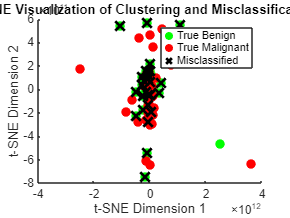

% Convert predictions{} to a column vector
predictedLabels = predictions_ground(:);  % Convert cell array to column vector

% Perform t-SNE to reduce dimensionality to 2D
reducedFeatures2D = tsne(normalizedFeatures, 'Perplexity', 30, 'Exaggeration', 12);

% Prepare data for plotting
trueLabels = labels(:);  % Ensure labels are in column vector form
benignIdx = strcmp(trueLabels, 'Benign');
malignantIdx = strcmp(trueLabels, 'Malignant');

% Plot true labels
figure;
scatter(reducedFeatures2D(benignIdx, 1), reducedFeatures2D(benignIdx, 2), 50, 'g', 'filled', 'DisplayName', 'True Benign');
hold on;
scatter(reducedFeatures2D(malignantIdx, 1), reducedFeatures2D(malignantIdx, 2), 50, 'r', 'filled', 'DisplayName', 'True Malignant');

% Highlight misclassified points
mismatchIdx = ~strcmp(trueLabels, predictedLabels);
scatter(reducedFeatures2D(mismatchIdx, 1), reducedFeatures2D(mismatchIdx, 2), 100, 'kx', 'LineWidth', 2, 'DisplayName', 'Misclassified');

% Add legend and title
legend;
title('t-SNE Visualization of Clustering and Misclassifications');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
hold off;

% Display the table in a GUI window
%figure;
%uitable('Data', resultsTable{:,:}, 'ColumnName', resultsTable.Properties.VariableNames, ...
   % 'Position', [20 20 600 300]);